% Presetting
syms x y z omega phi psi p(x, y, z);
PosExtract=[0; 0; 0; 1];
p(x, y, z)=[x y z].';
Rotx(omega)=[1  0   0
            0   cos(omega)  -sin(omega)
            0   sin(omega)  cos(omega)];
Roty(phi)=[cos(phi) 0   sin(phi)
            0   1   0
            -sin(phi)   0   cos(phi)];
Rotz(psi)=[cos(psi) -sin(psi)   0
            sin(psi)    cos(psi)    0
            0   0   1];

% 3-DoF Manipulator Forward Kinematics
syms L1 L2 L3 theta1 theta2 theta3;

% Base to Arm1
angle12=theta1;
p12=p(0, L1, 0);
Rot12=Roty(-angle12);
T12=HomogeneousTransform(Rot12, p12, 1);

% Arm1 to Arm2
angle23=theta2;
p23=p(L2*cos(theta2), L2*sin(theta2), 0);
Rot23=Rotz(angle23);
T23=HomogeneousTransform(Rot23, p23, 1);

% Arm2 to Endpoint
angle34=theta3;
p34=p(L3*cos(theta3), L3*sin(theta3), 0);
Rot34=Rotz(angle34);
T34=HomogeneousTransform(Rot34, p34, 1);

% Transformation matrix of global to each joint
T13=T12*T23;
T14=T13*T34;

% Position of Endpoint according to Base Coordinate
p14=T14*PosExtract;

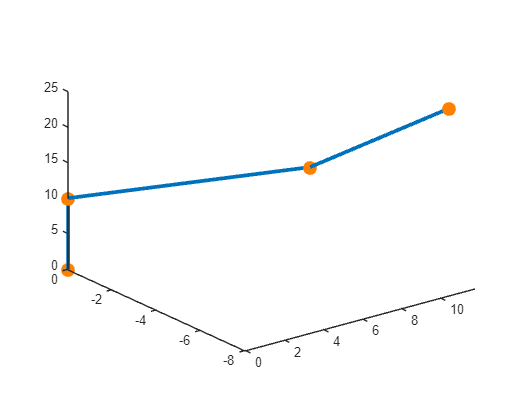

% 3-DoF Manipulator Kinematics test by plot graph
theta1=pi/6;
theta2=pi/6;
theta3=pi/6;
L1=10;
L2=10;
L3=10;

% Global to Base
angleg1=pi/2;
pg1=p(0,0,0);
Rotg1=Rotx(angleg1);
Tg1=HomogeneousTransform(Rotg1, pg1, 1);

% Base to Arm1
angle12=theta1;
p12=p(0, L1, 0);
Rot12=Roty(-angle12);
T12=HomogeneousTransform(Rot12, p12, 1);

% Arm1 to Arm2
angle23=theta2;
p23=p(L2*cos(theta2), L2*sin(theta2), 0);
Rot23=Rotz(angle23);
T23=HomogeneousTransform(Rot23, p23, 1);

% Arm2 to Endpoint
angle34=theta3;
p34=p(L3*cos(theta3), L3*sin(theta3), 0);
Rot34=Rotz(angle34);
T34=HomogeneousTransform(Rot34, p34, 1);

% Transformation matrix of Global Coordinate to each joint
Tg2=Tg1*T12;
Tg3=Tg2*T23;
Tg4=Tg3*T34;

% Position of each joint according to Global Coordinate
pg2=Tg2*PosExtract;
pg3=Tg3*PosExtract;
pg4=Tg4*PosExtract;

% plot
p = plot3([PosExtract(1,1), pg2(1,1), pg3(1,1), pg4(1,1)], [PosExtract(2,1), pg2(2,1), pg3(2,1), pg4(2,1)], [PosExtract(3,1), pg2(3,1), pg3(3,1), pg4(3,1)],'-o','LineWidth',3);
p.MarkerFaceColor = [1 0.5 0];
p.MarkerSize = 8;
p.MarkerEdgeColor = [1 0.5 0];